clc;
clear;
close all;
% ex3.a

N = 20;
P = 100000;
alfa = 0.1;
L = 1500;
C = 10;
f = 10000;
n = [10 20 30 40];

% variables for grah
PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));

PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

% variables for data
PLd = zeros(1, N);
PLv = zeros(1, N);
APDd = zeros(1, N);
APDv = zeros(1, N);
MPDd = zeros(1, N);
MPDv = zeros(1, N);
TT = zeros(1, N);

for i = 1:length(n)
    % Run the simulator N times
    for it = 1:N
            [PLd(it), PLv(it), APDd(it), APDv(it), MPDd(it), MPDv(it), TT(it)] = Sim3(L, C, f, P, n(i));
    end

    % Calculate Avg. Packet Delay for DATA packets
    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media
    APDd_terms(i) = term

    % Calculate Avg. Packet Delay for VoIP packets
    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media
    APDv_terms(i) = term

    % Calculate Packet Loss for DATA packets
    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media
    PLd_terms(i) = term

    % Calculate Packet Loss for VoIP packets
    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media
    PLv_terms(i) = term
end

APDd_values =     2.0226         0         0         0


APDd_terms =     0.0111         0         0         0


APDv_values =     1.6170         0         0         0


APDv_terms =     0.0118         0         0         0


PLd_values =     0.2387         0         0         0


PLd_terms =     0.0142         0         0         0


PLv_values =     0.0299         0         0         0


PLv_terms =     0.0050         0         0         0


APDd_values =     2.0226    2.3230         0         0


APDd_terms =     0.0111    0.0211         0         0


APDv_values =     1.6170    1.9250         0         0


APDv_terms =     0.0118    0.0188         0         0


PLd_values =     0.2387    0.4285         0         0


PLd_terms =     0.0142    0.0234         0         0


PLv_values =     0.0299    0.0496         0         0


PLv_terms =     0.0050    0.0059         0         0


APDd_values =     2.0226    2.3230    2.7329         0


APDd_terms =     0.0111    0.0211    0.0283         0


APDv_values =     1.6170    1.9250    2.3462         0


APDv_terms =     0.0118    0.0188    0.0275         0


PLd_values =     0.2387    0.4285    0.7612         0


PLd_terms =     0.0142    0.0234    0.0302         0


PLv_values =     0.0299    0.0496    0.0959         0


PLv_terms =     0.0050    0.0059    0.0080         0


APDd_values =     2.0226    2.3230    2.7329    3.2604


APDd_terms =     0.0111    0.0211    0.0283    0.0335


APDv_values =     1.6170    1.9250    2.3462    2.9002


APDv_terms =     0.0118    0.0188    0.0275    0.0345


PLd_values =     0.2387    0.4285    0.7612    1.4010


PLd_terms =     0.0142    0.0234    0.0302    0.0597


PLv_values =     0.0299    0.0496    0.0959    0.1831


PLv_terms =     0.0050    0.0059    0.0080    0.0125


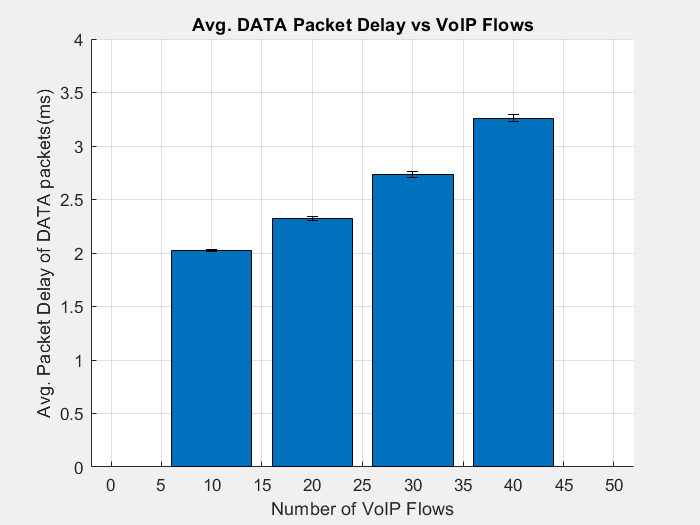


% Plot Avg. Packet Delay for DATA packets
figure(1);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDd_values');
ylim([0 4]);
er = errorbar(n, APDd_values', APDd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of DATA packets(ms)')
title('Avg. DATA Packet Delay vs VoIP Flows');
hold off;

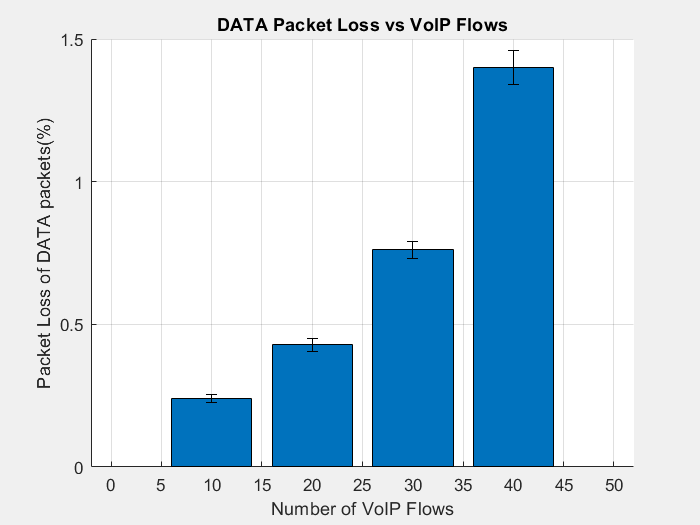


% Plot Avg. Packet Delay for VoIP packets
figure(2);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLd_values');
er = errorbar(n, PLd_values', PLd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of DATA packets(%)')
title('DATA Packet Loss vs VoIP Flows');
hold off;

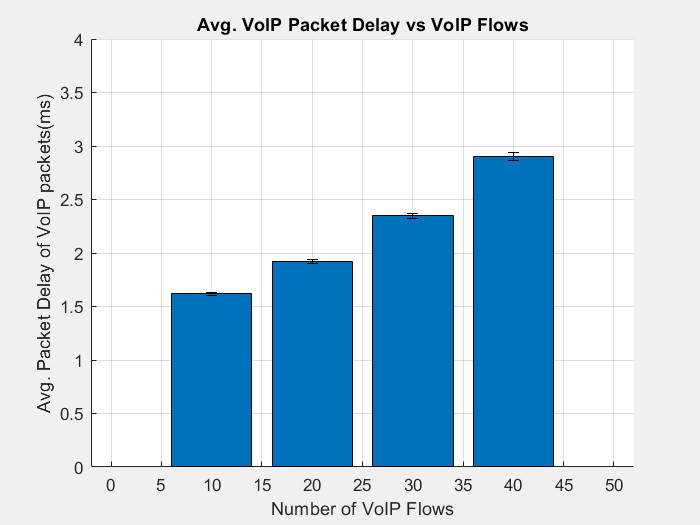


% Plot Packet Loss for DATA packets
figure(3);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDv_values');
ylim([0 4]);
er = errorbar(n, APDv_values', APDv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of VoIP packets(ms)')
title('Avg. VoIP Packet Delay vs VoIP Flows');
hold off;

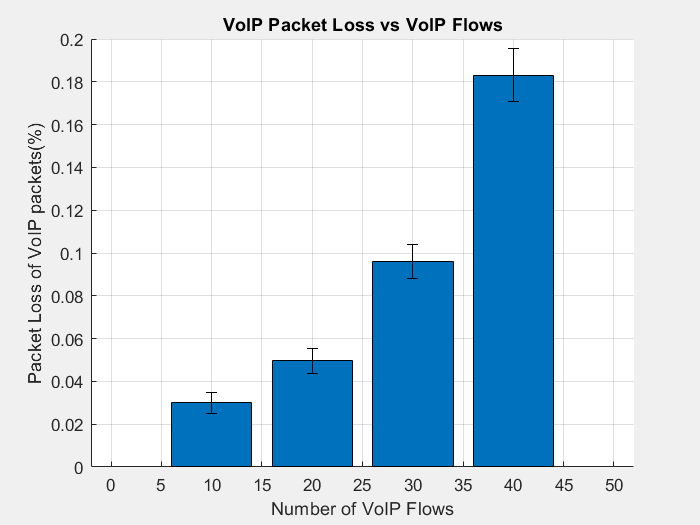


% Plot Packet Loss for VoIP packets
figure(4);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLv_values');
er = errorbar(n, PLv_values', PLv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of VoIP packets(%)')
title('VoIP Packet Loss vs VoIP Flows');
hold off;

clc;
clear;
close all;
% ex3.b

N = 20;
P = 100000;
alfa = 0.1;
L = 1500;
C = 10;
f = 10000;
n = [10 20 30 40];

% variables for grah
PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));

PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

% variables for data
PLd = zeros(1, N);
PLv = zeros(1, N);
APDd = zeros(1, N);
APDv = zeros(1, N);
MPDd = zeros(1, N);
MPDv = zeros(1, N);
TT = zeros(1, N);

for i = 1:length(n)
    % Run the simulator N times
    for it = 1:N
            [PLd(it), PLv(it), APDd(it), APDv(it), MPDd(it), MPDv(it), TT(it)] = Sim4(L, C, f, P, n(i));
    end

    % Calculate Avg. Packet Delay for DATA packets
    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media
    APDd_terms(i) = term

    % Calculate Avg. Packet Delay for VoIP packets
    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media
    APDv_terms(i) = term

    % Calculate Packet Loss for DATA packets
    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media
    PLd_terms(i) = term

    % Calculate Packet Loss for VoIP packets
    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media
    PLv_terms(i) = term
end

APDd_values =     2.0932         0         0         0


APDd_terms =     0.0115         0         0         0


APDv_values =     0.4598         0         0         0


APDv_terms =     0.0011         0         0         0


PLd_values =     0.2350         0         0         0


PLd_terms =     0.0125         0         0         0


PLv_values =     0.0267         0         0         0


PLv_terms =     0.0045         0         0         0


APDd_values =     2.0932    2.5396         0         0


APDd_terms =     0.0115    0.0248         0         0


APDv_values =     0.4598    0.4804         0         0


APDv_terms =     0.0011    0.0012         0         0


PLd_values =     0.2350    0.4530         0         0


PLd_terms =     0.0125    0.0220         0         0


PLv_values =     0.0267    0.0557         0         0


PLv_terms =     0.0045    0.0054         0         0


APDd_values =     2.0932    2.5396    3.0689         0


APDd_terms =     0.0115    0.0248    0.0189         0


APDv_values =     0.4598    0.4804    0.5001         0


APDv_terms =     0.0011    0.0012    0.0008         0


PLd_values =     0.2350    0.4530    0.7508         0


PLd_terms =     0.0125    0.0220    0.0267         0


PLv_values =     0.0267    0.0557    0.0864         0


PLv_terms =     0.0045    0.0054    0.0081         0


APDd_values =     2.0932    2.5396    3.0689    3.8263


APDd_terms =     0.0115    0.0248    0.0189    0.0420


APDv_values =     0.4598    0.4804    0.5001    0.5204


APDv_terms =     0.0011    0.0012    0.0008    0.0011


PLd_values =     0.2350    0.4530    0.7508    1.3330


PLd_terms =     0.0125    0.0220    0.0267    0.0507


PLv_values =     0.0267    0.0557    0.0864    0.1508


PLv_terms =     0.0045    0.0054    0.0081    0.0090


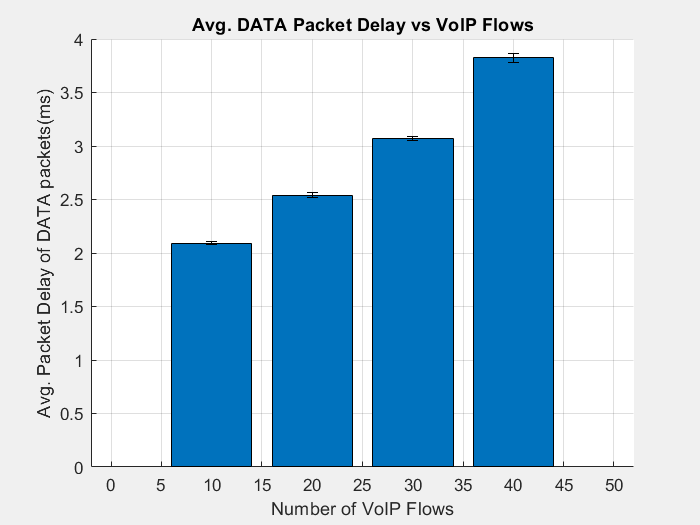


% Plot Avg. Packet Delay for DATA packets
figure(1);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDd_values');
ylim([0 4]);
er = errorbar(n, APDd_values', APDd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of DATA packets(ms)')
title('Avg. DATA Packet Delay vs VoIP Flows');
hold off;

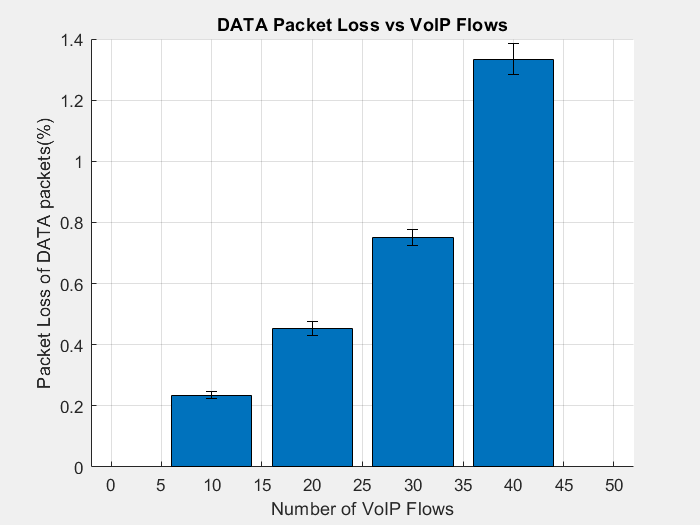


% Plot Avg. Packet Delay for VoIP packets
figure(2);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLd_values');
er = errorbar(n, PLd_values', PLd_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of DATA packets(%)')
title('DATA Packet Loss vs VoIP Flows');
hold off;

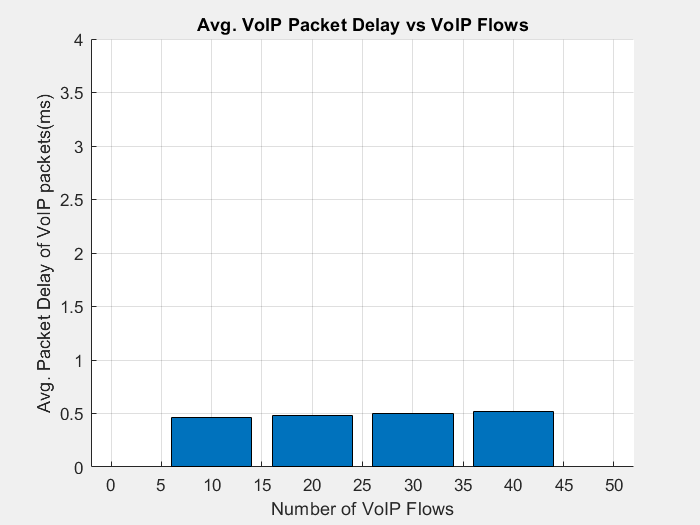


% Plot Packet Loss for DATA packets
figure(3);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, APDv_values');
ylim([0 4]);
er = errorbar(n, APDv_values', APDv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Avg. Packet Delay of VoIP packets(ms)')
title('Avg. VoIP Packet Delay vs VoIP Flows');
hold off;

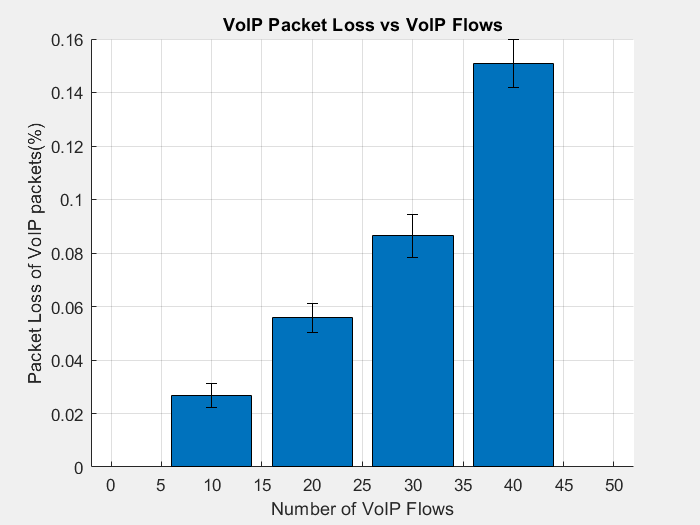


% Plot Packet Loss for VoIP packets
figure(4);
set(gcf,'Visible','on')
hold on;
grid on;
bar(n, PLv_values');
er = errorbar(n, PLv_values', PLv_terms);
er.Color = [0 0 0];
er.LineStyle = 'none';
xlabel('Number of VoIP Flows')
ylabel('Packet Loss of VoIP packets(%)')
title('VoIP Packet Loss vs VoIP Flows');
hold off;

#### 3.d)Use simulator Sim4A to estimate the same performance parameters as in 3.a and 3.b for p = 90%. Justify the differences in the performance values obtained for each service, and the differences between these results and the results of experiment 3.b. Draw all relevant conclusions.

N = 20;
P = 100000;
alfa = 0.1; % 90% confidence interval
L = 1500;
C = 10;
F = 10000;
n = [10 20 30 40];
p = 0.9;

PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));


PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

PLd = zeros(1,N);
APDd = zeros(1,N);
PLv = zeros(1,N);
APDv = zeros(1,N);


for i = 1:length(n)
    for x = 1:N
        [PLd(x),PLv(x),APDd(x),APDv(x),MPDd(x),MPDv(x),TT(x)] = Sim4A(L, C, F, P, n(i), p);
    end

    fprintf('For n = %d VoIP flows \n', n(i));
    
    % Calculate packet loss of data

    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media;
    PLd_terms(i) = term;
    fprintf('PacketLoss of data(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate packet loss of VoIP

    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media;
    PLv_terms(i) = term;
    fprintf('PacketLoss of VoIP(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of data

    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media;
    APDd_terms(i) = term;
    fprintf('Av. Packet Delay of data(ms)     = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of VoIP

    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media;
    APDv_terms(i) = term;
    fprintf('Av. Packet Delay of VoIP(ms)     = %0.2e +- %0.2e\n',media,term);
end

For n = 10 VoIP flows 


PacketLoss of data(%)             = 3.61e-01 +- 1.69e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 2.03e+00 +- 1.26e-02


Av. Packet Delay of VoIP(ms)     = 4.58e-01 +- 9.34e-04


For n = 20 VoIP flows 


PacketLoss of data(%)             = 6.24e-01 +- 1.89e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 2.42e+00 +- 1.90e-02


Av. Packet Delay of VoIP(ms)     = 4.78e-01 +- 1.25e-03


For n = 30 VoIP flows 


PacketLoss of data(%)             = 1.02e+00 +- 3.29e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 2.92e+00 +- 2.54e-02


Av. Packet Delay of VoIP(ms)     = 4.99e-01 +- 1.25e-03


For n = 40 VoIP flows 


PacketLoss of data(%)             = 1.71e+00 +- 4.50e-02


PacketLoss of VoIP(%)             = 0.00e+00 +- 0.00e+00


Av. Packet Delay of data(ms)     = 3.58e+00 +- 3.22e-02


Av. Packet Delay of VoIP(ms)     = 5.19e-01 +- 1.32e-03


#### 3.e)Repeat experiment 3.d considering now p = 60%. Justify the differences in the performance values obtained for each service, and the differences between these results and the results of experiments 3.b and 3.d. Draw all relevant conclusions.

p = 0.6;

PLd_values = zeros(1,length(n));
APDd_values = zeros(1,length(n));
PLv_values = zeros(1,length(n));
APDv_values = zeros(1,length(n));


PLd_terms = zeros(1,length(n));
APDd_terms = zeros(1,length(n));
PLv_terms = zeros(1,length(n));
APDv_terms = zeros(1,length(n));

PLd = zeros(1,N);
APDd = zeros(1,N);
PLv = zeros(1,N);
APDv = zeros(1,N);


for i = 1:length(n)
    for x = 1:N
        [PLd(x),PLv(x),APDd(x),APDv(x),MPDd(x),MPDv(x),TT(x)] = Sim4A(L, C, F, P, n(i), p);
    end

    fprintf('For n = %d VoIP flows \n', n(i));
    
    % Calculate packet loss of data

    media = mean(PLd);
    term = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    PLd_values(i) = media;
    PLd_terms(i) = term;
    fprintf('PacketLoss of data(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate packet loss of VoIP

    media = mean(PLv);
    term = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    PLv_values(i) = media;
    PLv_terms(i) = term;
    fprintf('PacketLoss of VoIP(%%)             = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of data

    media = mean(APDd);
    term = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    APDd_values(i) = media;
    APDd_terms(i) = term;
    fprintf('Av. Packet Delay of data(ms)     = %0.2e +- %0.2e\n',media,term);
    
    % Calculate avg. packet delay of VoIP

    media = mean(APDv);
    term = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    APDv_values(i) = media;
    APDv_terms(i) = term;
    fprintf('Av. Packet Delay of VoIP(ms)     = %0.2e +- %0.2e\n',media,term);
end
